# EE105 : Voltage Supply Design

# Name: Buddy Ugwumba SID: 862063029

## Sec. 1

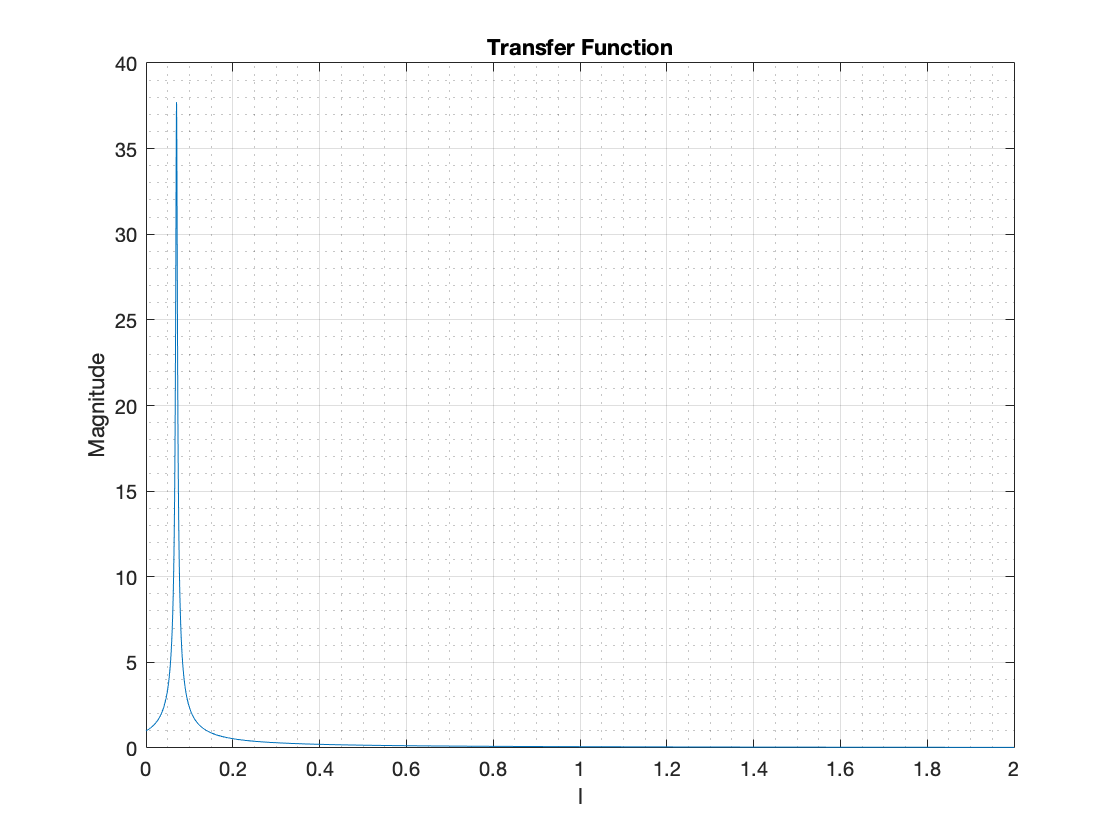

% Define constant variables (for imaginary number, try: clear i; a = 1+2*i)
R = 1000;
C = 100e-6;
w = 2*pi*60;
s = 1i*w;
clear i;
a = 1+2i;
% Set a vector for L, for your lab report, using the L below,
L = 0:1e-6:2;
% Search 'polyval' in MATLAB documentation
% Define the numerator coefficients and denominator coefficients for L
numerator = [s R];
denominator = [C*s^(3) (R*C*s^(2) + 2*s) R];
% Using 'polyval' fuctions and element-wise computation operation to
% generate Transfer function H_s(L)
H_s = polyval(numerator,L);
H_s_2 = polyval(denominator,L);
H_s_l = H_s./H_s_2;
% Get the magnitude of H_s (Try 'abs'), let's call it 'mag_H'
mag_H = abs(H_s_l);
% Plot mag_H versus L
figure
plot(L, mag_H);
% Labels, title, grid on.
xlabel('l');
ylabel('Magnitude');
title('Transfer Function')
grid on
grid minor

Find the value of L ** (5'')**

It's fine if you find the value manully through the 'plot'. 

**5'' points bonus** will be given if you use 'find' funtion to get the value of L.

% Similar to what you did in the previous lab, you should use 'find'
% function
% Find the closest value for the magnitude = 0.1
% (Similar idea with Lab 3: 4.1 Part 1, method 2)

You output result should be 

youngL = find(abs(mag_H-0.1)==(min(abs(mag_H-0.1))));
L(youngL)

ans = 0.7793

## Sec.2 

**Define the diode function diode.m**

**Define a function file called 'def'. Define the value of R,C,L,N. It will used in the 'MATLAB function' block.**

(a) **(10'')**

Show your answer. You can insert the image.

(b)  **(10'')**

Requirements same as (a)

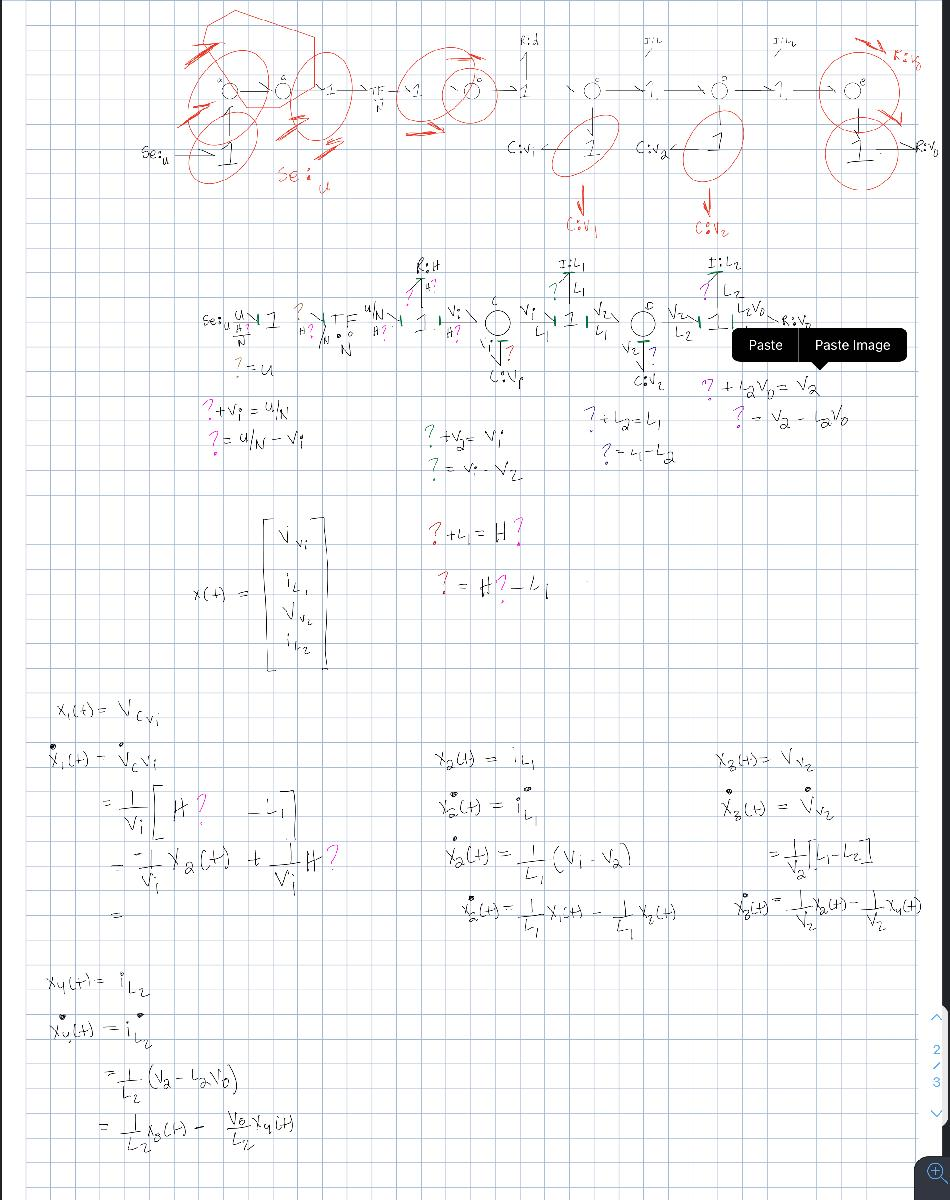

(c)

Show your Simulink model **(10'')**

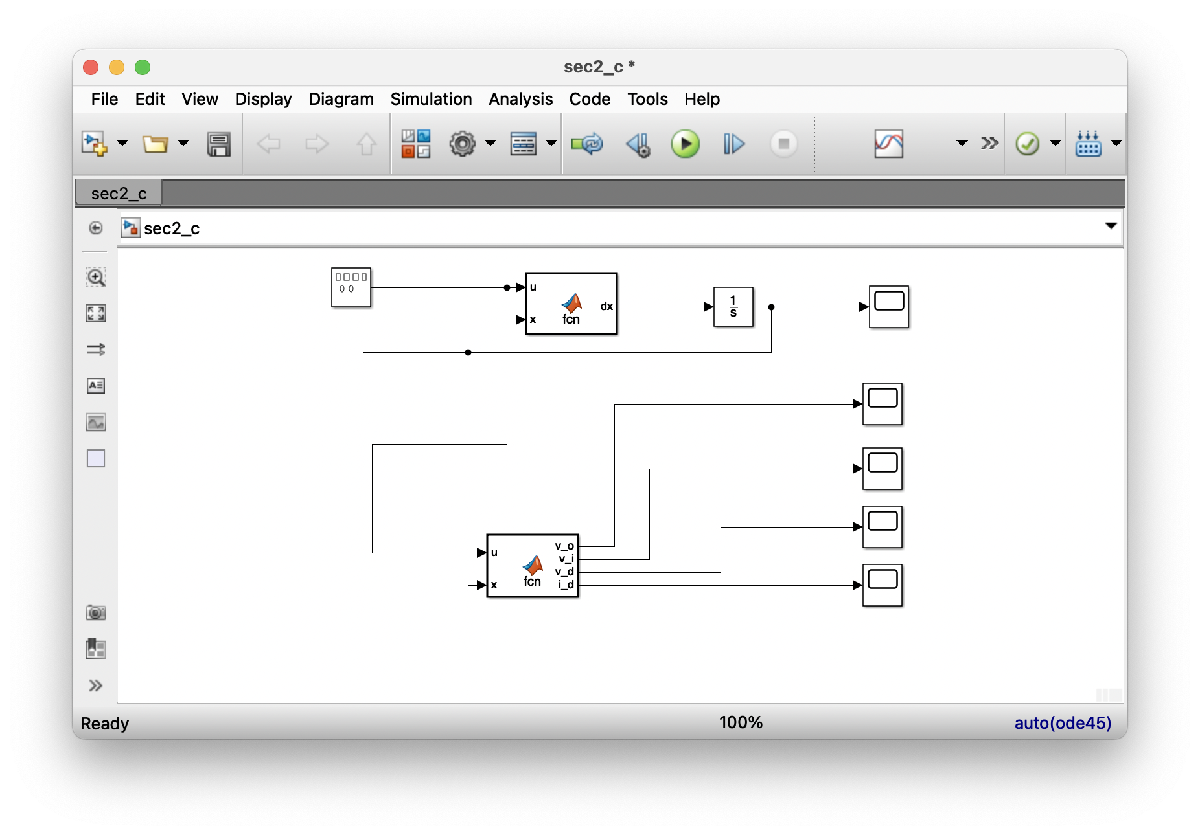

(d)

Show **4 figures (scopes)** for 4 outputs in vector y, State which one is for which output **(20'')**

Give the figure for different figure numbers, because you may will use it in the next question.

Explain each figures for different outputs. **(10'')**

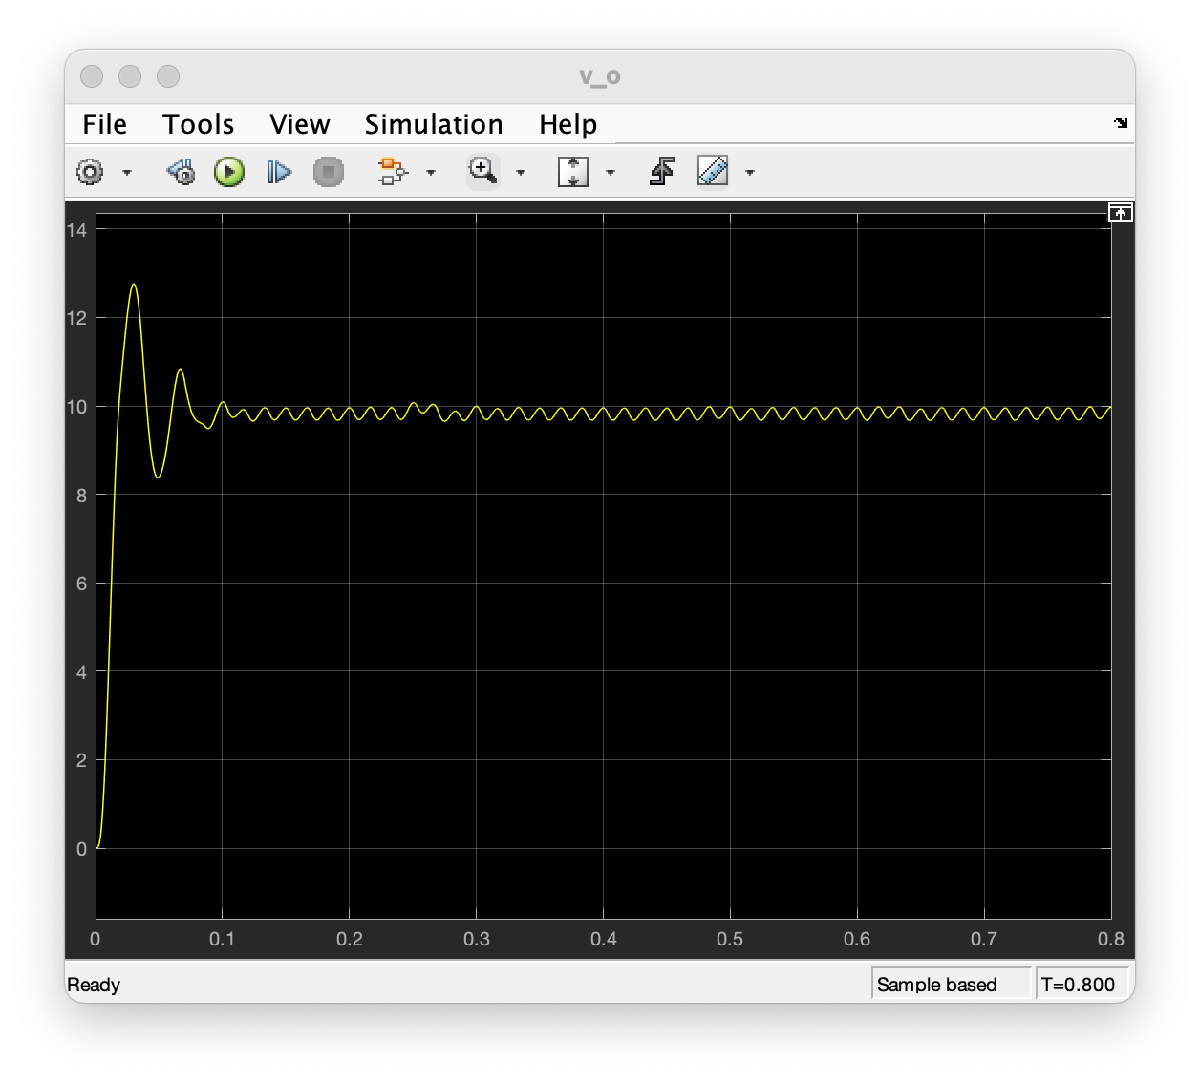

v_o is the output of the circuit. we can see its steady state response is around 0.1s. 

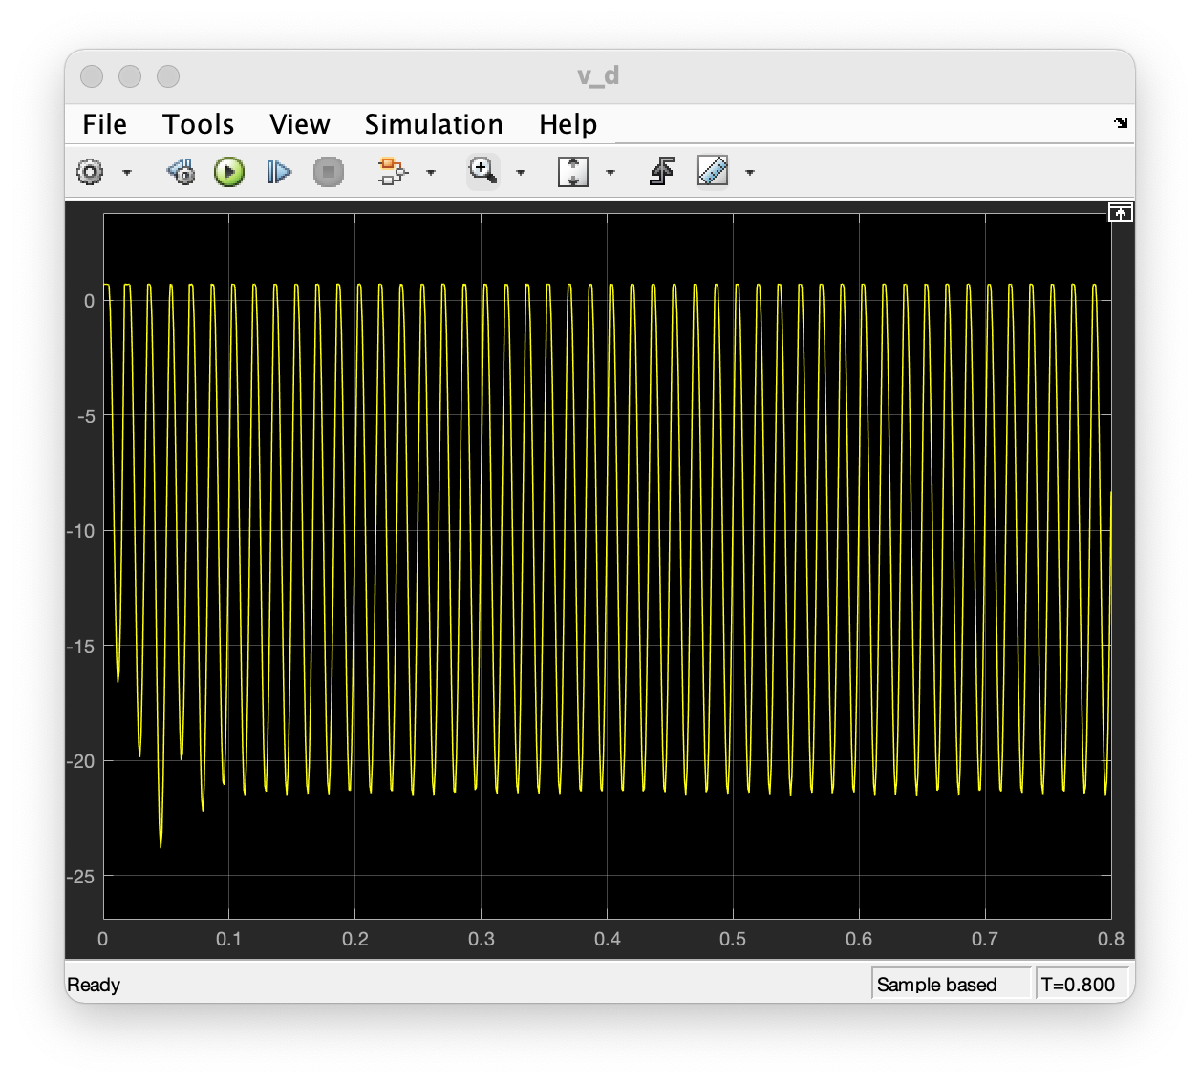

v_d is the voltage across the diode. because the voltage source has enough voltage, the diode is in active mode. and reaches its saturation point at 0.1s as well. 

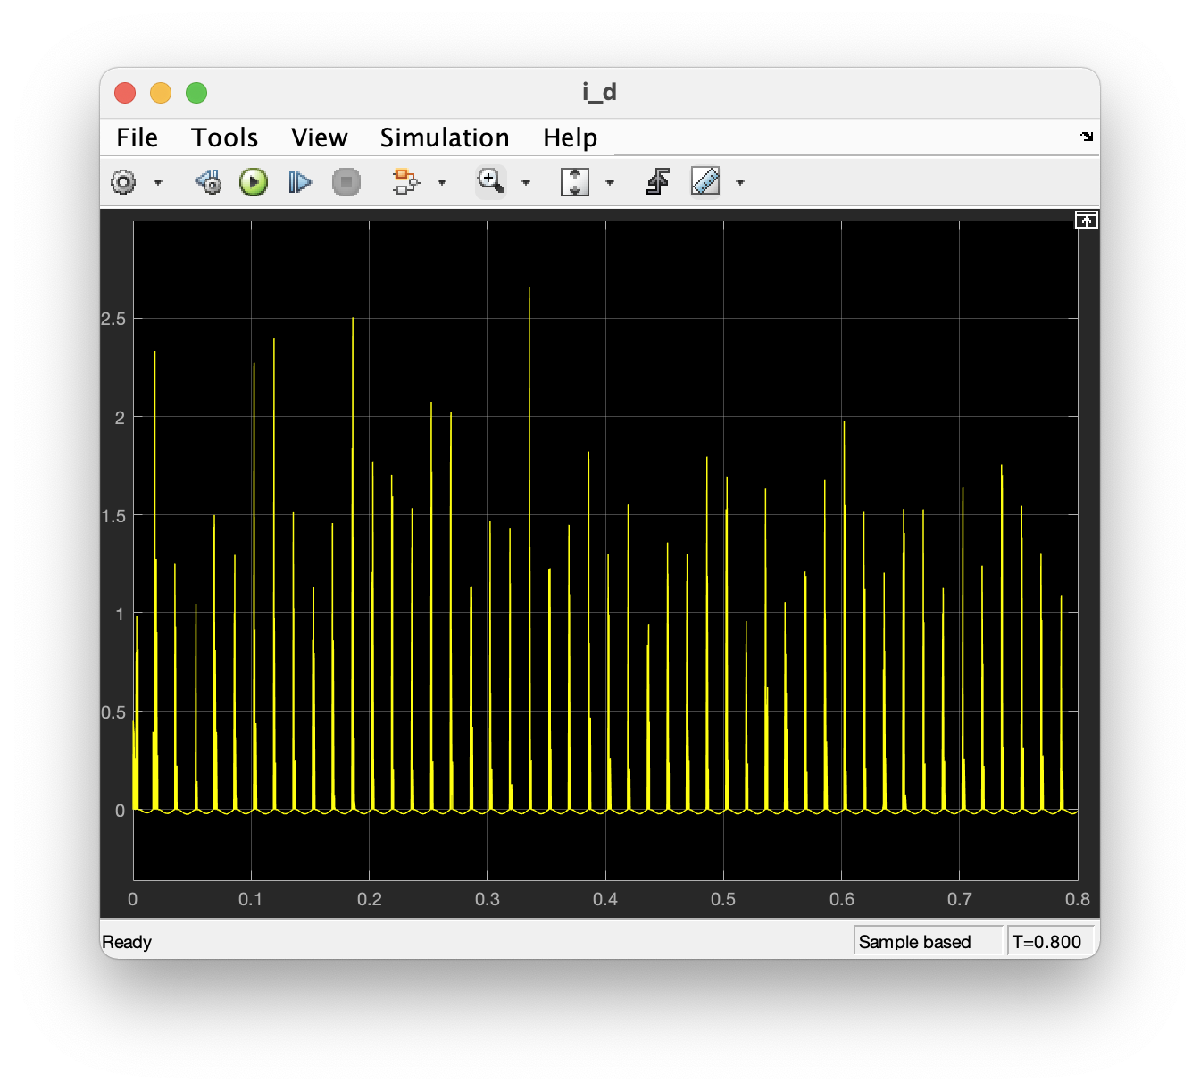

i_d represents the current of the dioe. Its fluctation is due to the capacitor. 

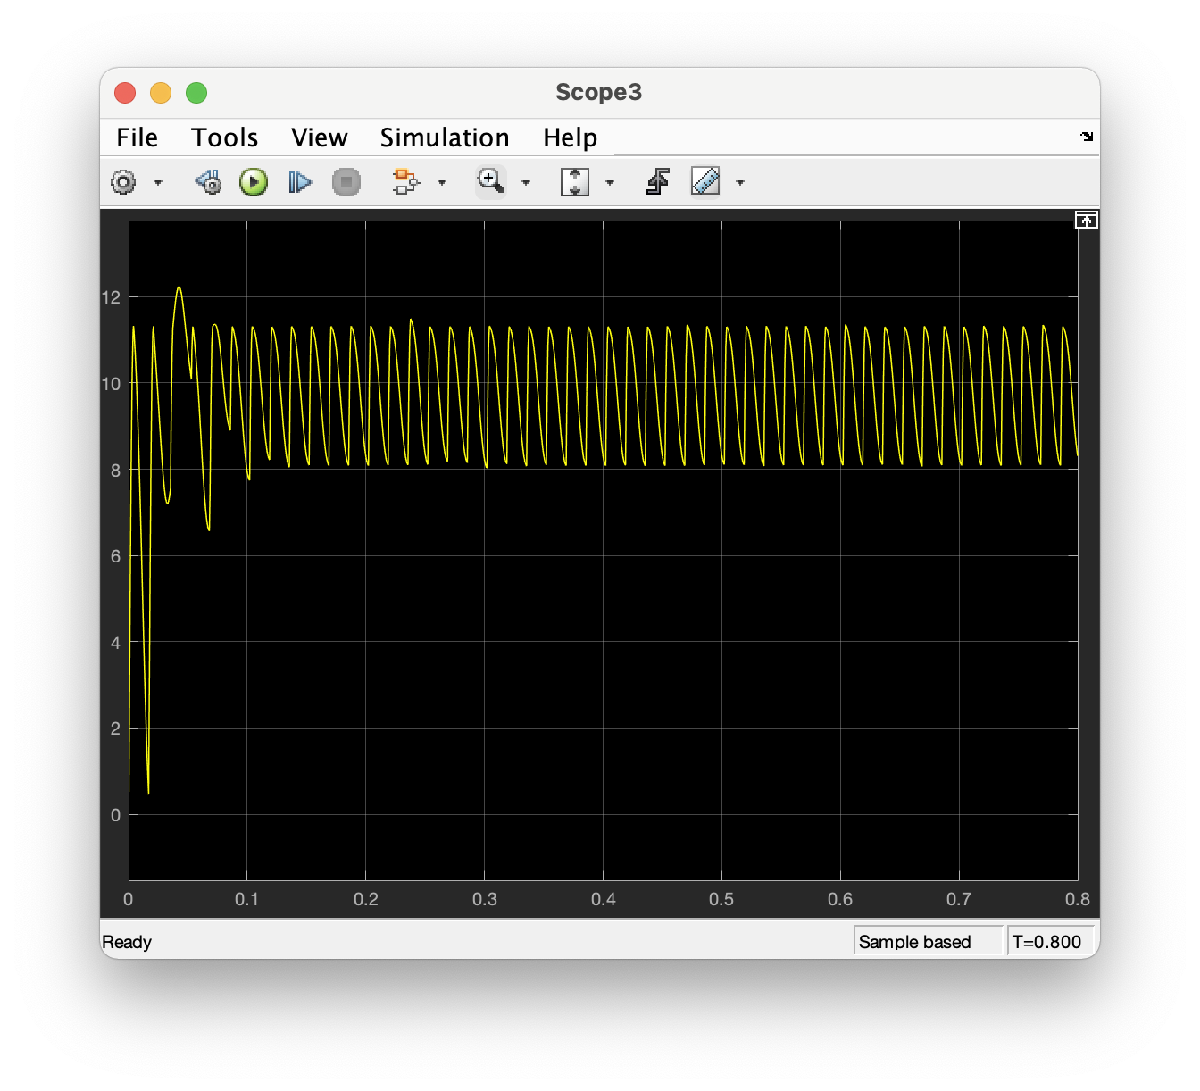

v_i is the coltage accross the capacitor. it reaches steady state at around 0.1s. 

(e)

i. **(5'')**

I would surmise that the purpose of the left portion of the circuit is to convert the voltage source from the ac to dc

ii. **(5'')**

The purpose of the right portion of the circuit is to provide the now converted dc voltage to the load

iii. **(5'')**

The purpose of the capacitors is to make sure that there isn't large voltage change when the source is converted to dc. The purpose of the diode is to act as a half wave rectifier so that we only get the positive cycle of the sinusodial voltage source. The purpose of the transformer is to trade the voltage from the sinusodial source for current. This is done without effecting the total electric power. This current is then passed through the diode and the capacitor, which act as a halfwave rectifier. The purpose of the inductor is to supply energy to the circuit to keep current flowing during the "off" switching periods and enables topographies where the output voltage is higher than the input voltage.inductor supplies energy to ensure that the

(f)

Using 'cursor measurement' measure the max and min in the steady-state oscillation.

percentage variation = $\frac{\max -\min }{\left(\max +\min \right)/2}$.

Show the percentage variations for R = 100,200,300,400,500,600,700,800,900,1000. Plot the percentage variation versus R. **(5'')**

 Explain the shape of the graph? **(5'')**

R = [100 200 300 400 500 600 700 800 900 1000];
Percentage = ones(1,length(R));
Percentage(1)=Percentage_Variation(6.764e+00, 6.466e+00);

variation = 0.0450

Percentage(2)=Percentage_Variation(8.176e+00, 7.816e+00);

variation = 0.0450

Percentage(3)=Percentage_Variation(8.821e+00, 8.459e+00);

variation = 0.0419

Percentage(4)=Percentage_Variation(9.184e+00, 8.842e+00);

variation = 0.0379

Percentage(5)=Percentage_Variation(9.428e+00, 9.100e+00);

variation = 0.0354

Percentage(6)=Percentage_Variation(9.597e+00, 9.281e+00);

variation = 0.0335

Percentage(7)=Percentage_Variation(9.711e+00, 9.414e+00);

variation = 0.0311

Percentage(8)=Percentage_Variation(9.822e+00, 9.526e+00);

variation = 0.0306

Percentage(9)=Percentage_Variation(9.899e+00, 9.614e+00);

variation = 0.0292

Percentage(10)=Percentage_Variation(9.952e+00, 9.677e+00);

variation = 0.0280

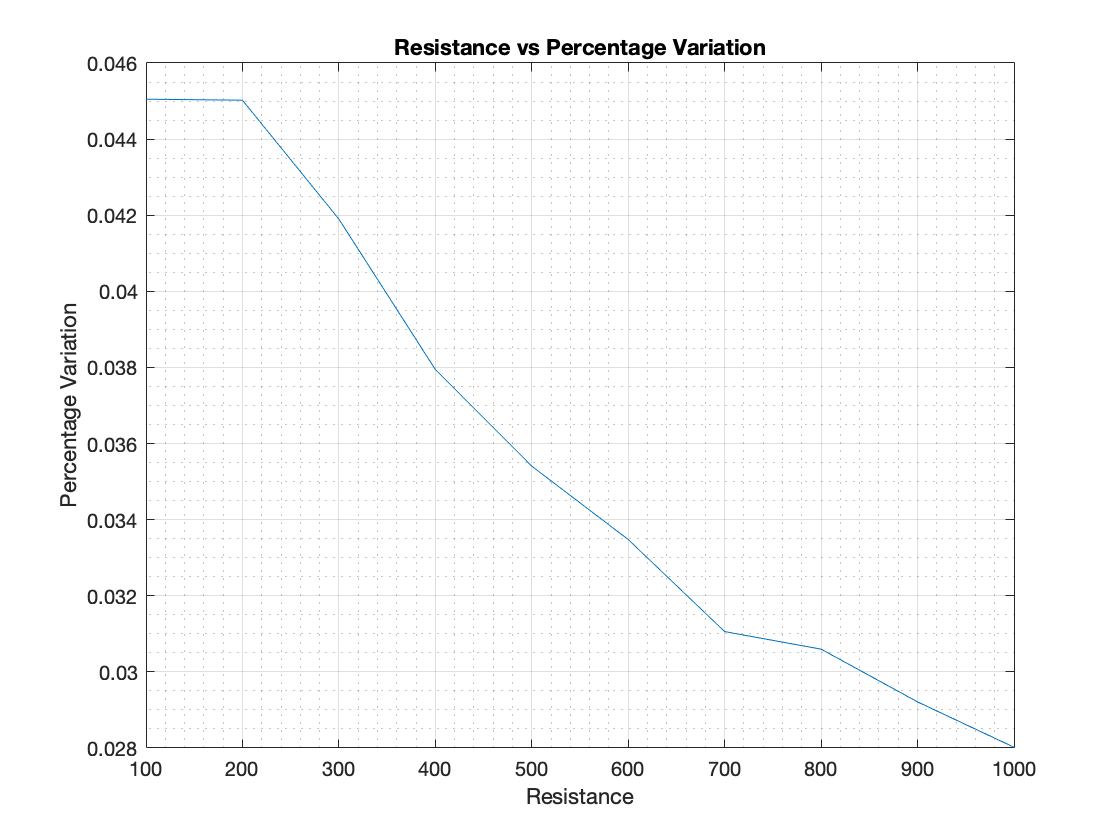

figure
plot(R, Percentage);
xlabel('Resistance');
ylabel('Percentage Variation');
title('Resistance vs Percentage Variation')
grid on
grid minor

percentage = ones(1,length(R));
percentage(1) = Percentage_Variation(6.764e+00, 6.466e+00);

variation = 0.0450